# Simulations of Brownian particle motion by the Euler–Maruyama method

Emma Gau

University of California -- Santa Barbara, Department of Electrical and Computer Engineering

## Abstract

A stochastic differential equation (SDE) aims to relate a stochastic process to its composition of random components and base deterministic function. As the relation process is prolonged over time, solutions arise under an initial condition and boundary conditions. Therefore solutions of stochastic differential equations exist and are unique (see app.). For this simulation, the Euler–Maruyama (EM) method will be used to approximate and simulate standard Brownian particle motion.

## 1 Brownian Motion

## 1.1 Discretized Brownian Paths

A scalar *standard Brownian motion* $W\left(t\right)$ over $\left\lbrack 0,T\right\rbrack$ where $t\in \left\lbrack 0,T\right\rbrack$, has conditions 

- 
$$W\left(0\right)=0$$


- For $0\le s<T$, the increment $W\left(t\right)-W\left(s\right)$ is normally distributed with mean zero and variance $t-s$.

- For $0\le s<t<u<v\le T$, the increments $W\left(t\right)-W\left(s\right)$ and $W\left(v\right)-W\left(u\right)$ are independent.

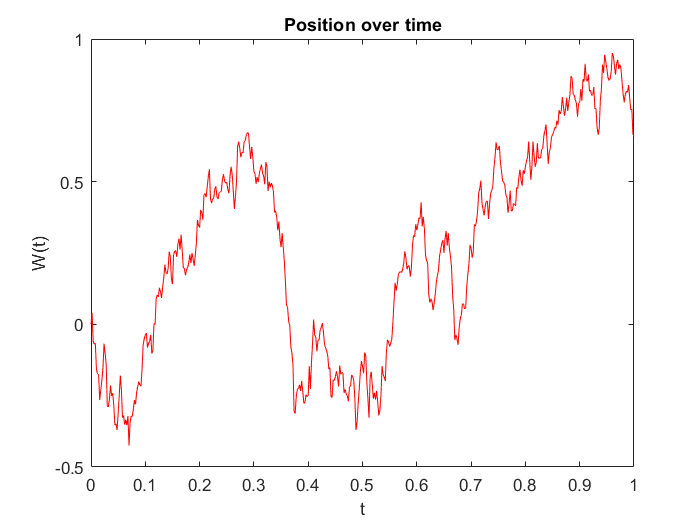

randn('state',100)
T = 1;
N = 500;
dt = T/N;

dW = sqrt(dt) * randn(1,N);
W = cumsum(dW);

plot([0:dt:T],[0,W],'r-')
xlabel('t')
ylabel('W(t)')
title('Position over time')

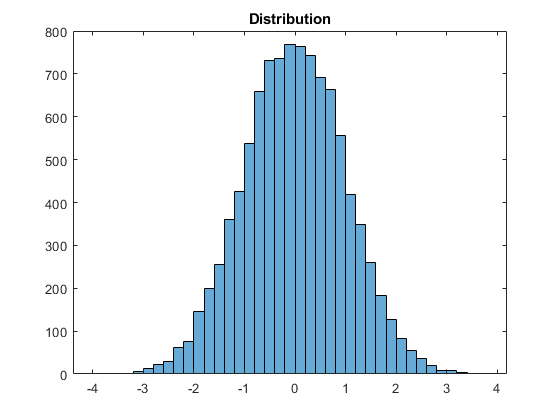

histogram(randn(1,1e4))
set(gcf, 'Color', 'w');
title('Distribution')

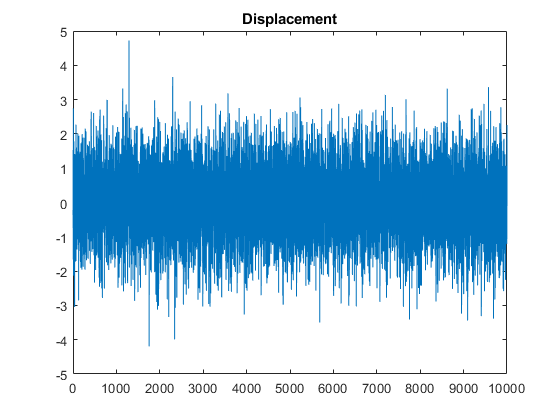

plot(randn(1,1e4))
set(gcf, 'Color', 'w');
title('Displacement')

## 1.2 Approximation of the Stochastic Integral

Integrating a function $h$ with respect to Brownian motion gives the stochastic integral $\int_{0}^{T} h(t)dW(t)$, which can also be written as


$$\sum_{j=0}^{N-1} h\left(t_j \right)\left(W\left(t_{j+1} \right)-W\left(t_j \right)\right)$$


by the "left" *Riemann sum *(see Appendix). Alternatively, the "midpoint" Riemann sum yields


$$\sum_{j=0}^{N-1}h\left(\frac{t_{j}+t_{j+1}}{2}\right)(t_{j+1}-t_{j}).$$


Evaluating the stochastic integrals for each approximation yields exact solutions


$$\frac{1}{2}\sum_{j=0}^{N-1}\left(W(t_{j+1})^2-W(t_{j})^2-(W(t_{j+1})-W(t_{j}))^2\right)
 \\=\frac{1}{2}\left(W(T)^2-W(0)^2-\sum_{j=0}^{N-1}(W(t_{j+1})-W(t_{j}))^2\right)
 $$


and


$$ \frac{1}{2}\left(W(T)^2-W(0)^2\right)\:+\:\sum_{j=0}^{N-1}\Delta{Z_{j}}(W(t_{j+1})-W(t_{j}))  \text{,}\quad\Delta{Z_j}=N\left(\frac{\Delta{t}}{4}\right).$$


Therefore $\int_{0}^{T} h(t)dW(t)$ is defined as the limit of a Riemann sum.

## 1.3 The Ito integral

As expected, the summation term from the exact solutions will yield value $T$ and variance $O(\delta{t})$. Therefore, $\delta t$ approaches constant $T$, giving the *Ito integral*


$$\int_{0}^{T}W(t)dW(t)=\frac{1}{2}W(T)^2-\frac{1}{2}T\text{.}$$


Similarly, the midpoint Riemann sum gives the *Stratonovich integral*


$$\int_0^TW(t)dW(t)=\frac12W(T)^2.$$


We will apply the definition of the Ito integral to simulate the solutions of a stochastic differential equation. This is known as the Euler–Maruyama method.

## 2 The The Euler–Maruyama method

The solution $X\left(t\right)$ to a stochastic differential equation (SDE) satisfies


$$X(t)=X_0\,+\,\int_0^tf(s,X(s))ds\,+\,\int_0^tg(s,X(s))dW(s)\text{,}\quad0\leq{t}\leq{T}.$$


Notice the right integral uses the Ito integral form. Therefore it is taken with respect to Brownian motion.

## 2.1 Application of standard Brownian motion

We can then take the SDE form


$$dX(t)=f(t,X(t))dt\,+\,g(t,X(t))dW(t),\quad X(0)=X_0\text{,}\quad0\leq{t}\leq{T},$$


and using the base stochastic process of standard Brownian motion, discretize over the interval $\left\lbrack 0,T\right\rbrack$. Thus we can apply the approximations


$$\int_{t_n}^{t_{n+1}}g(s,X(s))dW(s)\approx g(t_n,X_n)\Delta W_n,\\
\int_{t_n}^{t_{n+1}}f(s,X(s))ds\approx a(t_n,X_n)\delta{t}.$$


Then the change $\textrm{dX}$of the stochastic process over infinitesimal time interval $\textrm{dt}\;$can be written

$dX=\mu(X(t))dt\,+\,\sigma(X(t) )dW(t)\text{,}\quad X(0)=X_0$,

where $\mu$ and $\sigma$ are constants, and $f(X)=\mu{X}$ and $g(X)=\sigma{X}$ in the approximations above.

## 3 Simulations of solutions using the EM method

## 3.1 Approximate error and distribution

From $\textrm{dX}$, the exact solution is given by


$$X(t)=X_0e^{\sigma{W(t)+(\mu-\frac12\sigma^2)t}}.$$


We can vary the step size to obtain the *approximation error.* To do this we make Z independent runs of the simulation and compute

- 
$$\frac{1}{Z}\sum_{z=1}^Z \left|X_0 e^{\sigma W^{z\left\lbrack N\right\rbrack +\left(\mu -\frac{\sigma^2 }{2}\right)T} } -X^z \left\lbrack N\right\rbrack \right|\approx$$

$$\mathbb{E}\left\vert X_T-X[N]\right\vert$$


- 
$$\left\vert\mathbb{E}\left(X_0e^{\sigma W_T+(\mu-\frac{\sigma^2}{2})T}\right)-\frac1Z\sum_{z=1}^ZX^z[N]\right\vert\approx\left\vert\mathbb{E}X_T-\mathbb{E}X[N]\right\vert$$


where $N$ is an independent draw and $N\left\lbrack 0\ldotp \ldotp N-1\right\rbrack$ is an array of $N$ independent draws from $N\left(0,1\right)\ldotp$

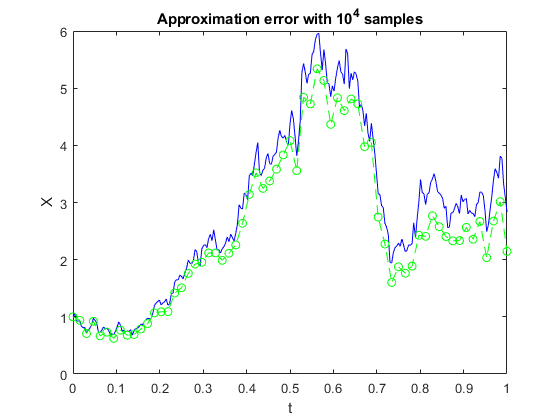

clear

randn('state',100) 

lambda = 2;
mu = 1;
Xnot = 1;
T = 1;
N = 2^8;
dt = 1/N; 
dW = sqrt(dt)*randn(1,N); 
W = cumsum(dW); 

X_exact = Xnot*exp((lambda-.5*mu^2)*([dt:dt:T])+mu*W);
plot([0:dt:T],[Xnot,X_exact],'b-');
hold on


R = 4;
Dt = R*dt;
L = N/R;
X_EM = zeros(1,L);
X_temp = Xnot;

for j = 1:L
    Winc = sum(dW(R*(j-1)+1:R*j));
    X_temp = X_temp + Dt*lambda*X_temp + mu*X_temp*Winc;
    X_EM(j) = X_temp;
end

plot([0:Dt:T],[Xnot,X_EM],'g--o')
hold off

xlabel('t');
ylabel('X');
title('Approximation error with 10^4 samples')

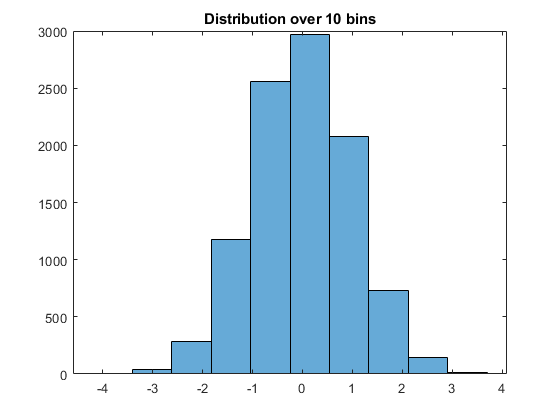

histogram(randn(1,1e4),10)
title('Distribution over 10 bins')

## 3.2 Mean and Variance

The mean of the distribution can be obtained using


$$\bar{x}=N^{-1}\sum{x_i}\text{.}$$


Taking the average difference between the points and $\bar{x}$ gives


$$m_1=\frac{\sum{x_i-\bar{x}}}{N}.$$


However, we know that the result will take an approximate value 0 from a condition of normally distributed discretized Brownian paths. Since $\sum{\bar{x}}$ is represented by $N$ lots of $\bar{x}$,

$N\bar{x}=N\frac{\sum{x_i}}{N}=\sum{x_i}$.

Thus, the average difference can be rewritten as


$$m_1=\frac{\sum{x_i}-\sum{\bar{x}}}{N}
\\=\frac{\sum{x_i}-\sum{x_i}}{N}
\\=0.$$


This problem arises since the positive differences above the mean offset the negative differences below it. Thus the mean may be defined as the value in which the differences between the variable values and mean equal zero. Alternatively, we may solve for the *average squared difference *instead:


$$m_2=\frac{\sum{(x_i-\bar{x})^2}}{N}.$$


This is the second moment or *variance,* and taking $\sqrt{m_2 \;}$ gives the *standard deviation.* We take five intervals from the histogram distribution, compute the mean and variance, and plot as a function of time.

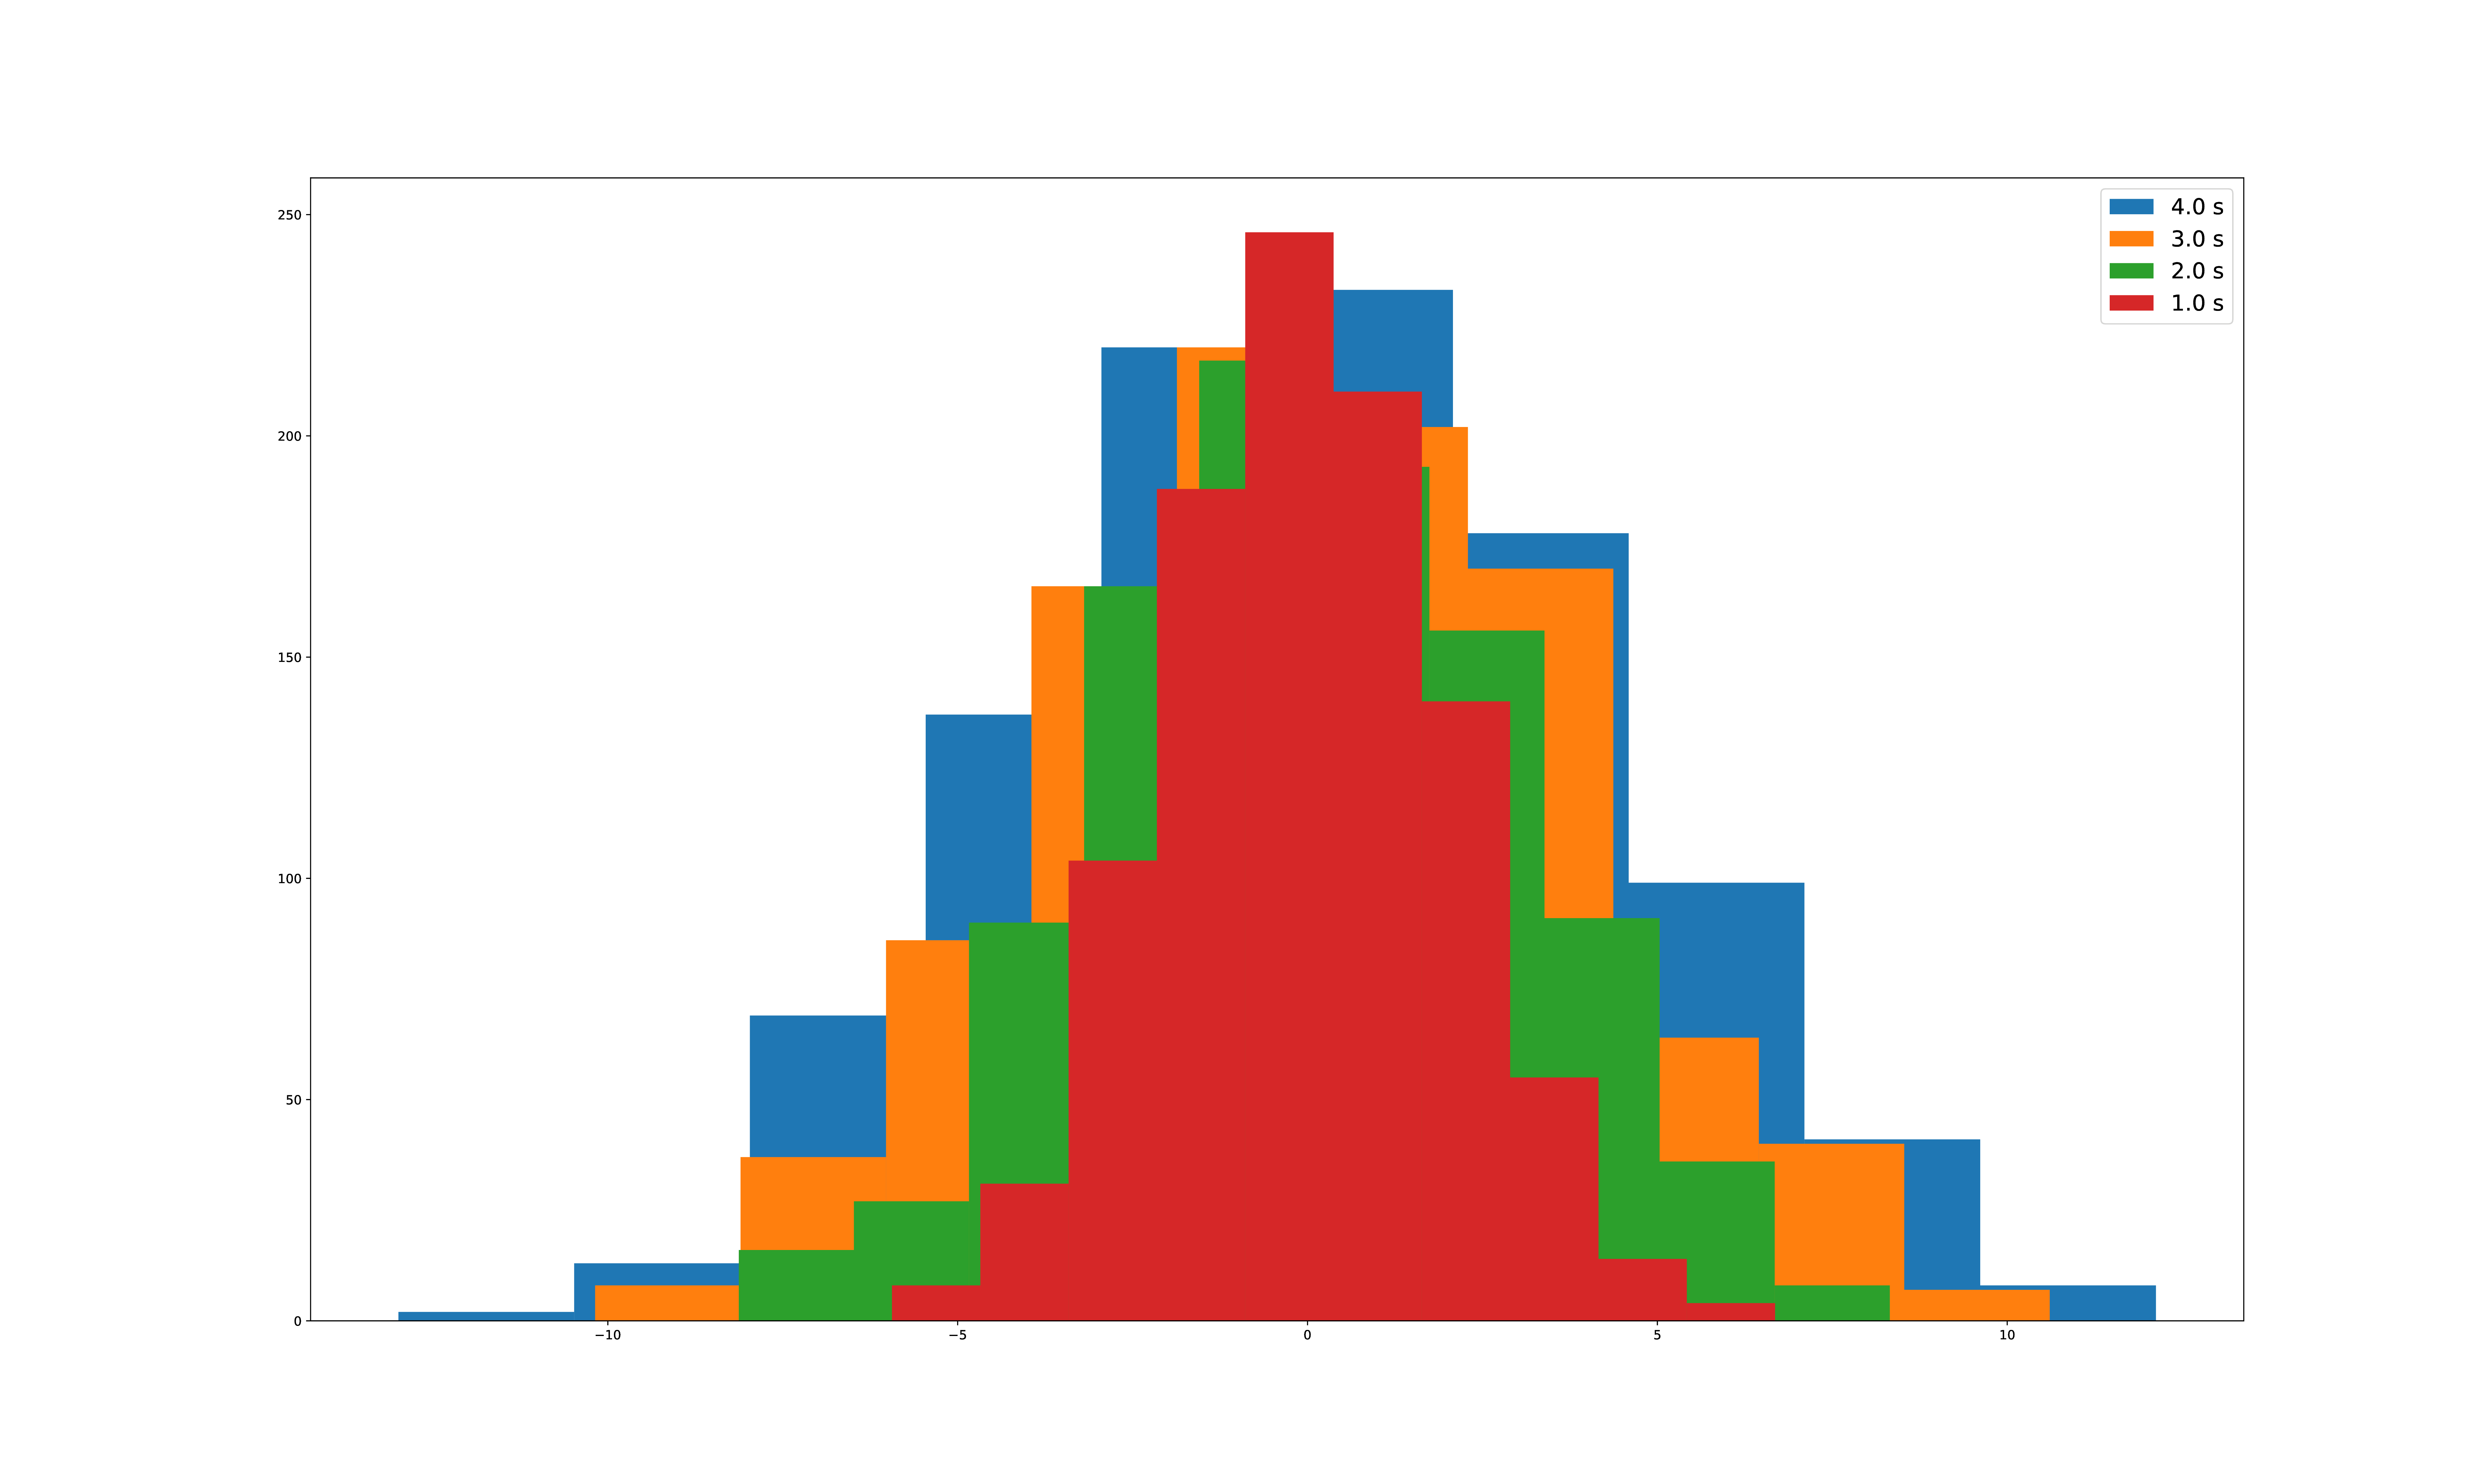

However, the histogram remains uninformative since it is dependent on the choice of bins. We normalize it to obtain the probability distribution,

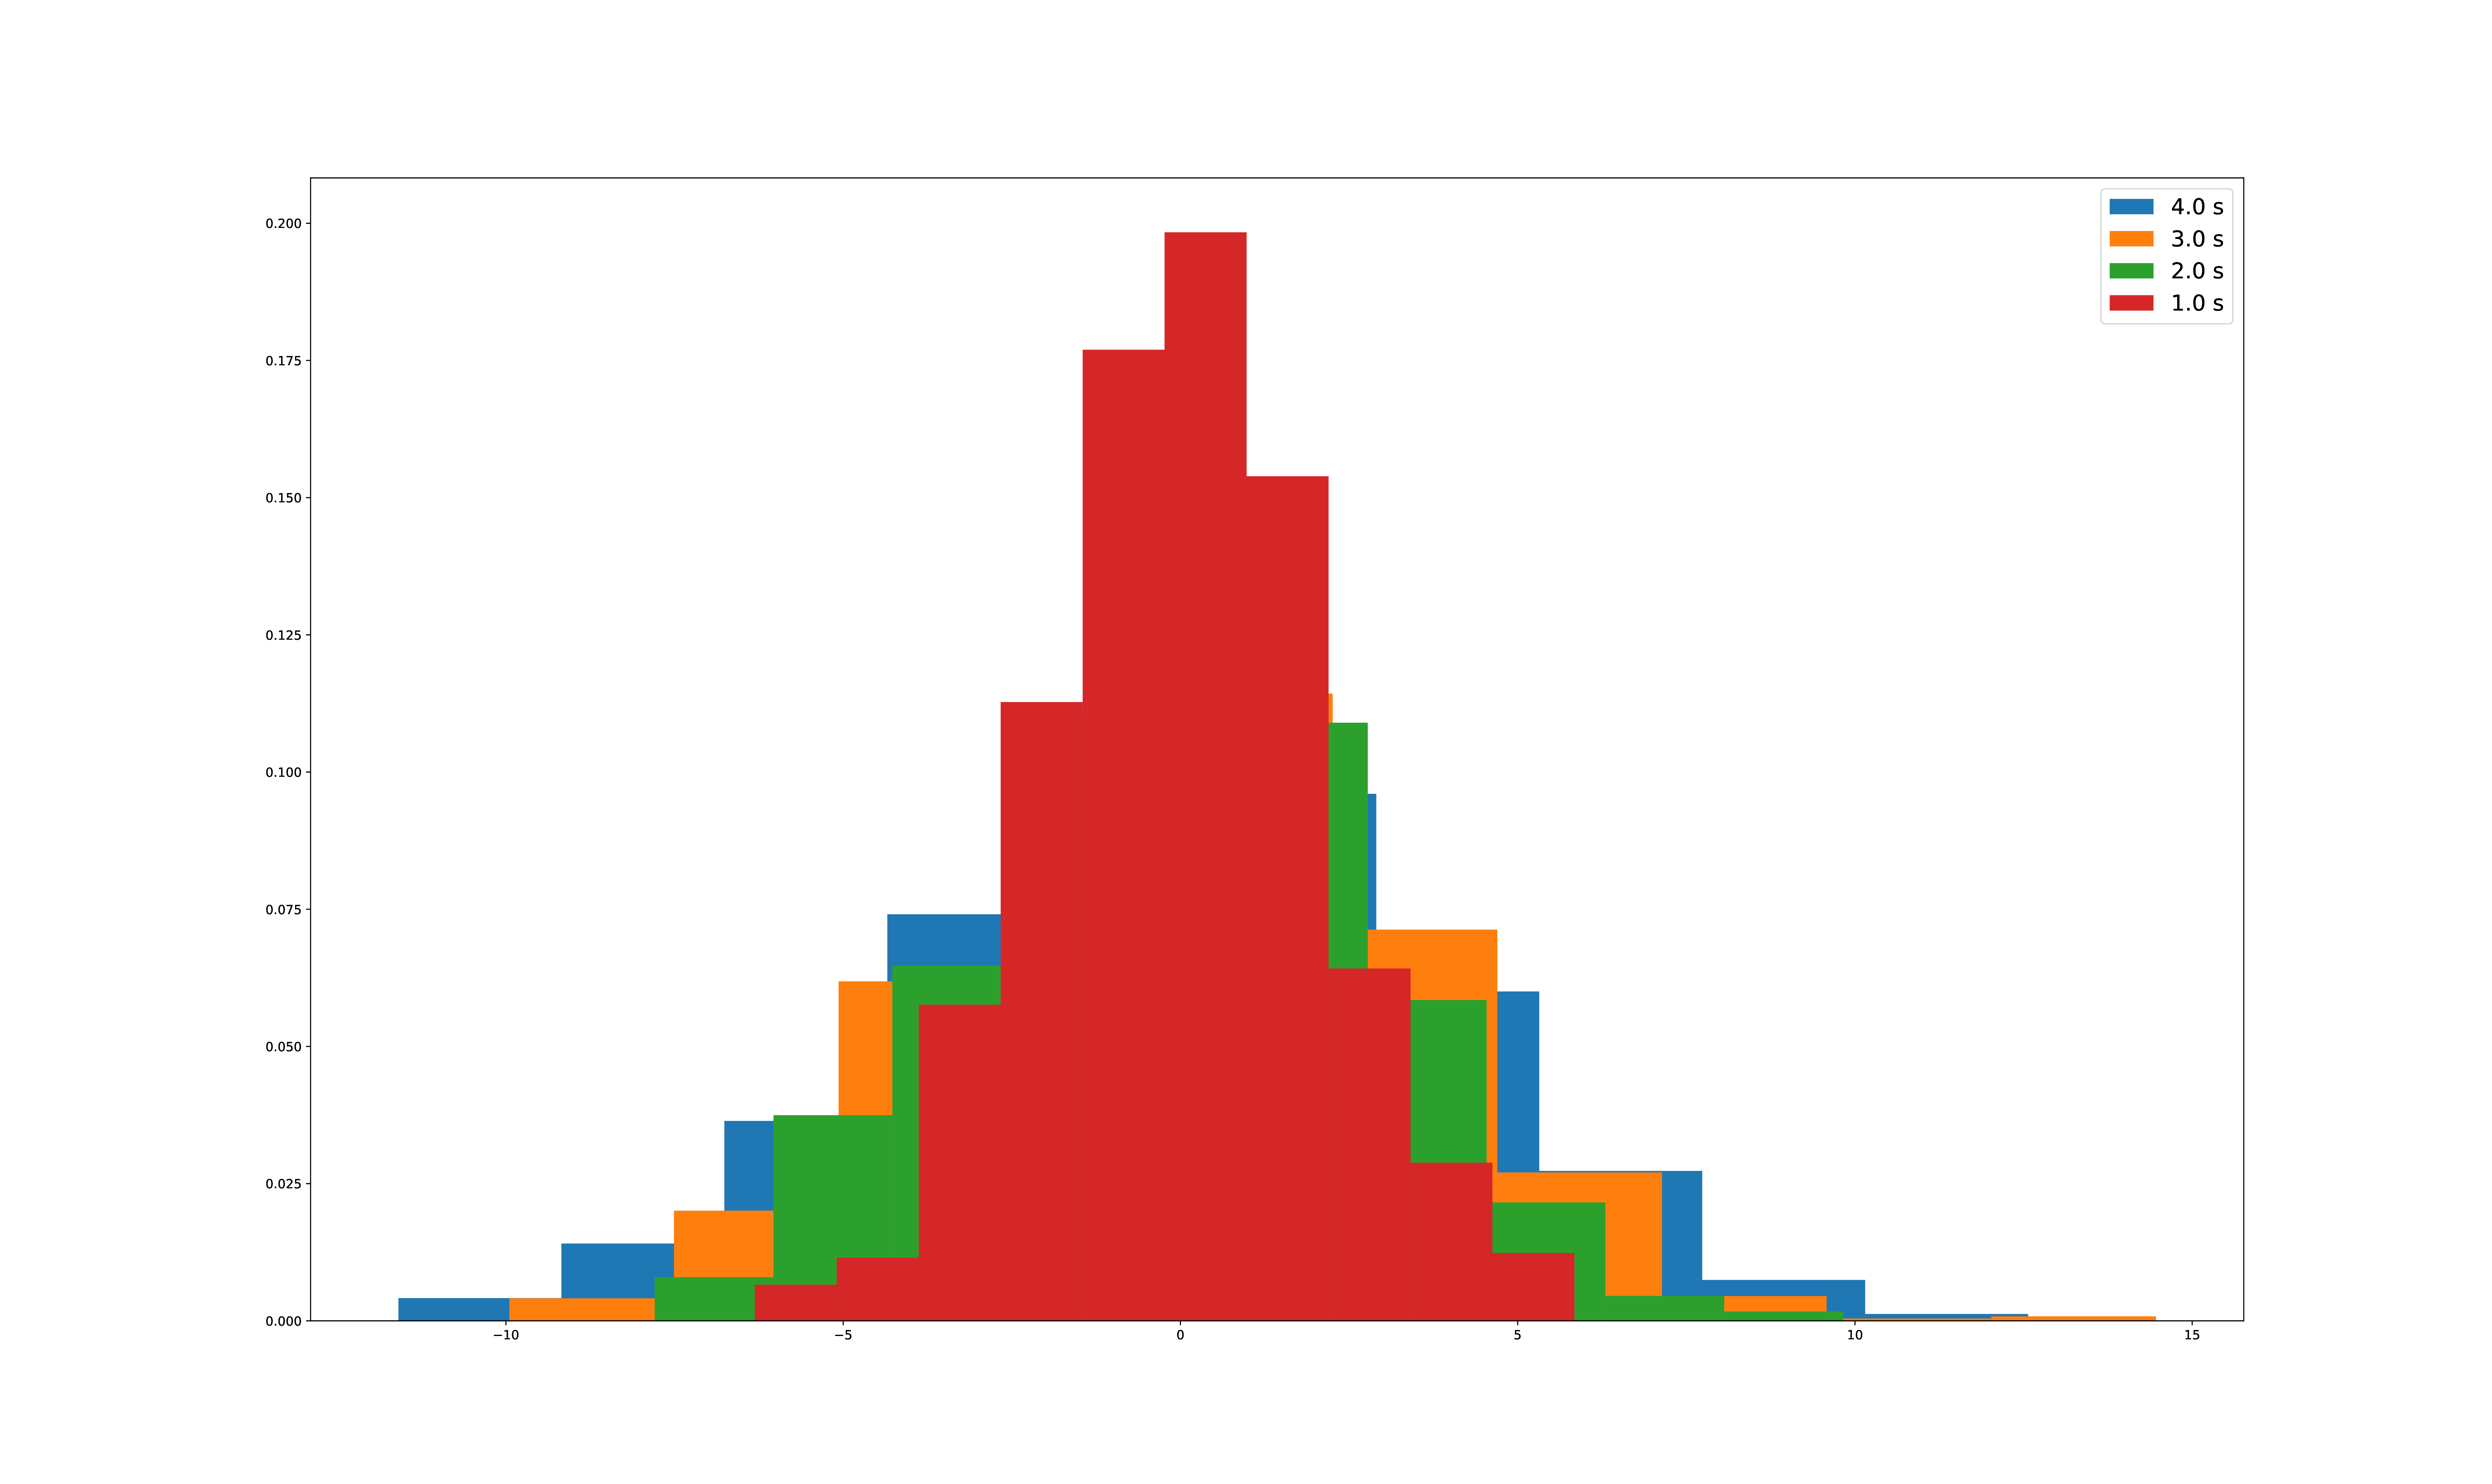

## 4 Comparison to the Diffusion Equation model

## 4.1 Solving by superposition

Given the diffusion equation


$$\frac{\partial{\rho}}{\partial{t}}=D\nabla^2{\rho}$$


and initial condition


$$\rho(x,0)=\delta(x-y),$$


we first solve for the diffusion equation with


$$\int_{-\infty}^\infty\left\vert \rho(x,t) \right\vert^2 dx<\infty,\qquad 0\leq{t}.$$


Notice the solution is set to be square integrable to ensure the uniqueness of the solutions. Taking the complex separable solution gives


$$\rho(x,t)=e^{-k^2t}e^{ikx}$$


with frequencies k. The solutions can then be combined by Fourier superposition to obtain the general solution


$$\rho(x,t)=\frac{1}{\sqrt{2\pi}}\int_{-\infty}^\infty e^{-k^2t}e^{ikx}\hat\delta_y(k)dk.$$


Thus the initial condition


$$\rho(x,0)=\delta(x-y)$$


is satisfied, where


$$\hat\delta_y(k)=\frac{1}{\sqrt{2\pi}}e^{-iky}.$$


Given the *fundamental solution* equation (see Appendix)


$$L(\rho)=\int_0^l\delta(x-\beta)f(\beta)d\beta=f(x),$$


we arrive at the fundamental solution


$$F(x-y,t)=\frac{1}{2\sqrt{\pi t}}e^{\frac{-(x-y)^2}{4t}}.$$


## 4.2 Solving numerically

It is also possible to numerically compute the solutions to the diffusion equation. Let


$$\rho(x,0)=\delta(x-0)$$



$$u(x,0)=G(x-0,0,\sigma^2),
$$



$$G=\frac{1}{\sqrt{2\pi\sigma^2}}e^{\frac{-x^2}{2}\sigma^2}.$$


We then iterate over $G$. Plotting over different time steps gives the diffusion equation model

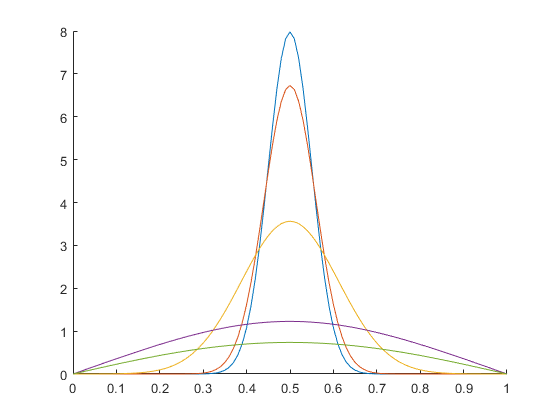

clear;

numx = 101;   
numt = 2000;   
dx = 1/(numx - 1);
dt = 0.00005;

x = 0:dx:1;   

C = zeros(numx,numt);   

t(1) = 0;      
C(1,1) = 0;    
C(1,numx) = 0; 
mu = 0.5;
sigma = 0.05;

for i=2:numx-1
   C(i,1) = exp(-(x(i)-mu)^2/(2*sigma^2)) / sqrt(2*pi*sigma^2);
end

for j=1:numt
   t(j+1) = t(j) + dt;
   for i=2:numx-1
      C(i,j+1) = C(i,j) + (dt/dx^2)*(C(i+1,j) - 2*C(i,j) + C(i-1,j)); 
   end
end

figure
hold on
plot(x,C(:,1));
plot(x,C(:,11));
plot(x,C(:,101));
plot(x,C(:,1001));
plot(x,C(:,2001));
hold off

## Appendices

## A Existence–Uniqueness

For the stochastic differential equation

$dX=G(t,X(t))dt\,+\,H(t,X(t))dW(t),\qquad X(t_0)=X_0$,

assume

- Both $G\left(t,x\right)$ and $H\left(t,x\right)$ are continuous on $(t,x)\in[t_0,T]\times\mathbb{R}$.

- The coefficient functions $G$ and $H$ satisfy a Lipschitz condition:$\left\vert G(t,x)-G(t,y) \right\vert+\left\vert H(t,x)-H(t,y) \right\vert\leq K\vert x-y\vert.$

- The coefficient functions $G$ and $H$ satisfy a growth condition in the second variable$\vert G(t,x)\vert^2+\vert H(t,x)\vert^2\leq K(1+\vert x\vert^2)$ for all $t\in[t_0,T]$ and $x\in\mathbb{R}$.$.

Then the stochastic differential equation has a strong solution on $\left\lbrack t_0 ,T\right\rbrack$ that is continuous with probability 1.

## B Riemann sum for stochastic integrals

Given a suitable function $h$, the integral $\int_0^Th(t)dt $ may be approximated by the Riemann sum


$$\sum_{j=0}^{N-1}h(t_j)(t_{j+1}-t_j),\qquad t_j=j\delta{t}.$$


The integral may be defined by taking the limit $\delta t\to 0,$ giving


$$\sum_{j=0}^{N-1}h(t_j)(W(t_{j+1})-W(t_j))$$


which is an approximation to a stochastic integral $\int_0^Th(t)dW(t)$.

*This section adapted from: ”An Algorithmic Introduction to the Numerical Simulation of Stochastic Differential Equations”, by Desmond J. Higham, SIAM Review, Vol. 43*

## C Fundamental solutions of PDEs

Consider


$$L(u)=\delta(x-\beta),\qquad u(0)=u(l)=0,\qquad 0<x<l$$


Let Green’s function $u(x,\beta)=G(x,\beta)$ represent the solution. By linearity, we obtain the general solution


$$L(u)=f(x),\qquad u(0)=u(l)=0,\qquad 0<x<l$$


as a superposition integral


$$u(x)\equiv\int_0^lG(x,\beta)f(\beta)d\beta.$$


Thus


$$L(u)=\int_0^l\delta(x-\beta)f(\beta)d\beta=f(x).$$


## References

[1] C. Flynn, stochastic Documentation, readthedocs. org, Jan. 05, 2018. [Online]. Available: [https://media.readthedocs.org/pdf/stochastic/latest/stochastic.pdf.](https://media.readthedocs.org/pdf/stochastic/latest/stochastic.pdf.) [Accessed Feb. 18, 2018].

[2] M. Giles, Module 4: Monte Carlo path Simulation, Oxford University Mathematical Institute. [Online]. Available: https://people.maths.ox.ac.uk/gilesm. [Accessed: 20-Feb-2018].

[3] J. Palczewski, Numerical schemes for SDEs, MIMUW. [Online]. Available: https://www.mimuw.edu.pl/apalczew/CFPlecture5.pdf. [Accessed: 20-Feb-2018].

[4] D. Shuman, The Diffusion Equation. [Online]. Available: http://wwweng.lbl.gov/shuman/. [Accessed: 19-Feb-2018].